% for windows

addpath ('C:\Users\xavie\Desktop\localworking\spm12')
addpath ('C:\Users\xavie\Desktop\localworking\spm12\toolbox\suit')

myflatmap = figure

myflatmap =   Figure (1) with properties:

      Number: 1
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [387 366 560 420]
       Units: 'pixels'

  Show all properties


Data = suit_map2surf('mean_sz.nii','space','SPM', 'stats',@mode)


SPM12: suit_map2surf (v3.1)                        10:24:10 - 20/04/2019


Data =     0.1420
    0.1420
    0.4050
    0.1420
    0.3430
    0.3430
    0.3430
    0.8238
    0.8238
    0.4050


suit_plotflatmap(Data,'threshold',NaN,'cscale',[-1 1.3], 'cmap', jet)


SPM12: suit_plotflatmap (v3.1)                     10:24:22 - 20/04/2019


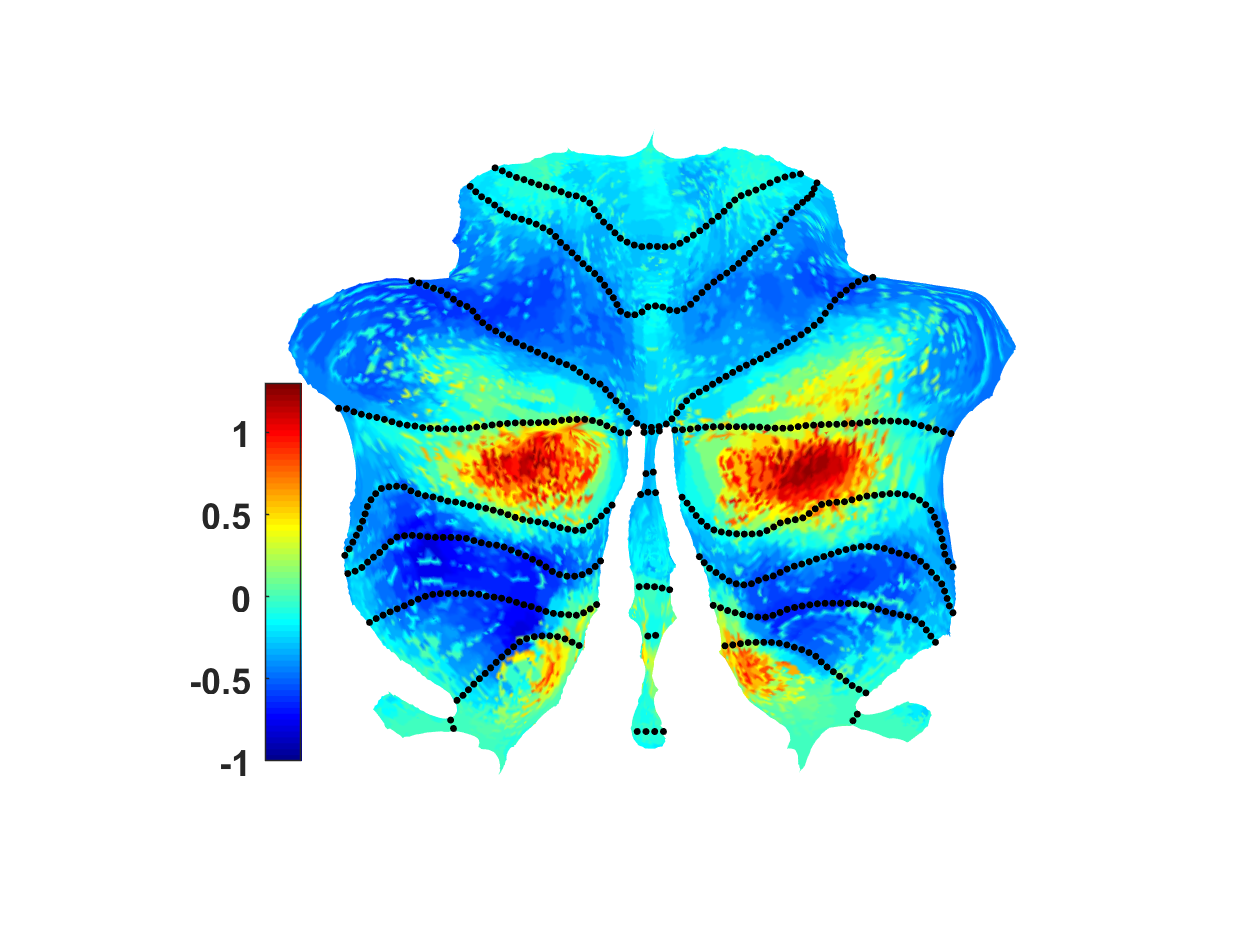

colormap jet
caxis([-1 1.3]) %this is for the colorbar, has to be the same as the cscale
colorbar('FontSize',12, 'AxisLocation', 'out', 'Location', 'west', 'FontWeight', 'bold', 'position', [.21 .195 .03 .4])
set(gca,'Visible','off')

set(gca,'xtick',[])
set(gca,'xticklabel',[])
set(gca,'ytick',[])
set(gca,'yticklabel',[])

fig.PaperUnits = 'inches';
set(gca,'xtick',[])

fig.PaperPosition = [0 0 19 19]; %sets size of image
saveas(myflatmap,'mean_sz_UniformColorScale','png')


myflatmap = figure

myflatmap =   Figure (2) with properties:

      Number: 2
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [387 366 560 420]
       Units: 'pixels'

  Show all properties


Data = suit_map2surf('mean_hc.nii','space','SPM', 'stats',@mode)


SPM12: suit_map2surf (v3.1)                        10:24:41 - 20/04/2019


Data =     0.2541
    0.2541
    0.5519
    0.2541
    0.4494
    0.4494
    0.4494
    0.9571
    0.9571
    0.5519


suit_plotflatmap(Data,'threshold',NaN,'cscale',[-1 1.3], 'cmap', jet)


SPM12: suit_plotflatmap (v3.1)                     10:24:43 - 20/04/2019


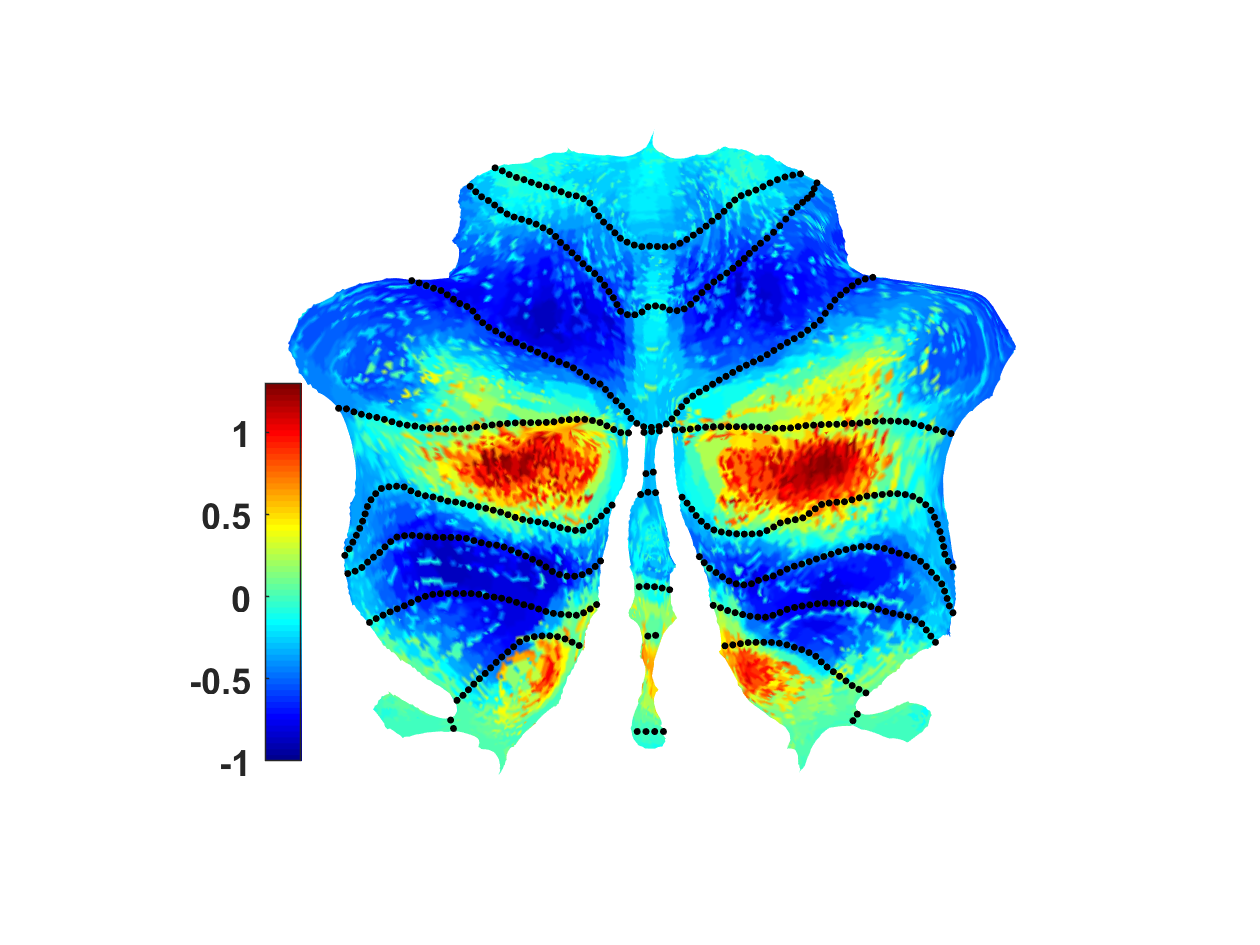

colormap jet
caxis([-1 1.3]) %this is for the colorbar, has to be the same as the cscale
colorbar('FontSize',12, 'AxisLocation', 'out', 'Location', 'west', 'FontWeight', 'bold', 'position', [.21 .195 .03 .4])
set(gca,'Visible','off')

set(gca,'xtick',[])
set(gca,'xticklabel',[])
set(gca,'ytick',[])
set(gca,'yticklabel',[])

fig.PaperUnits = 'inches';
set(gca,'xtick',[])

fig.PaperPosition = [0 0 19 19]; %sets size of image
saveas(myflatmap,'mean_hc_UniformColorScale','png')